# Comparison Preamp Settings

On 2021-06-17 I recorded 4 spectra of the pin solar cell that I contacted to study the SNR as a function of amplification factors of the EDMR pre amplifier. The spectra are saved in the files going from measurement 001 to 004. The spectra are acquired in the dark at 1.2V of forward bias.

clearvars, clear, clc, close all
addpath(genpath('D:\Profile\qse\Files\soft\software\Matlab'));

% File and Run options
Opt.LFolder = 'D:\Profile\qse\Files\_Pin SC EPRoC - Elexsys\20210617';
Opt.Ldir0 = dir([Opt.LFolder, '\*_0Deg.DTA']);
Opt.LPaths = [Opt.LFolder, '\', Opt.Ldir0.name];
Opt.Ldir90 = dir([Opt.LFolder, '\*_90Deg.DTA']);

Opt.SFolder = 'D:\Profile\qse\Files\Side projects\_Pin SC EPRoC - Elexsys\Images';

% Field offset (obtained from 013_calibration_NC60)
B0Offset = 1.763;
cw = struct();
ncw = 4;

for icw = 1:ncw
    LPath0_ = [Opt.LFolder, '\', Opt.Ldir0(icw).name];
    LPath90_ = [Opt.LFolder, '\', Opt.Ldir90(icw).name];

    [cw(icw).xRaw, cw(icw).yRaw, cw(icw).Params] = ...
        eprloadQuad(LPath0_, LPath90_);
    
    cw(icw).x = (cw(icw).xRaw - B0Offset)/10; % mT
    newStr = strsplit(Opt.Ldir0(icw).name, '_');
    cw(icw).Title = [newStr{3}, ' ', newStr{4}];
end

#### Baseline correction

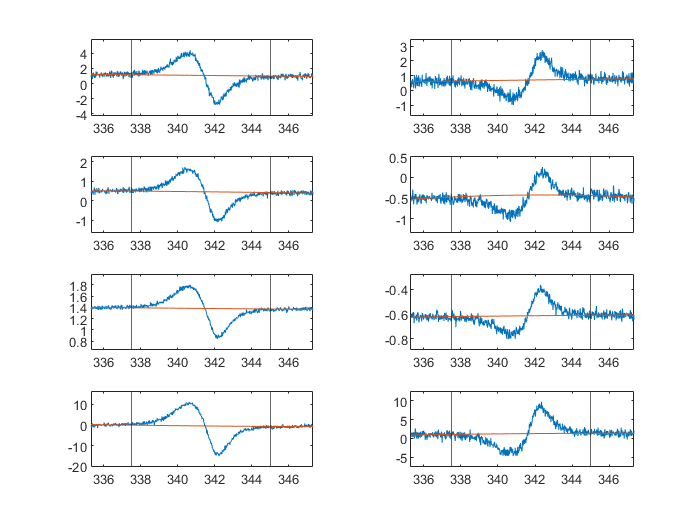

Opt.Bl.Order = 2;
Opt.Bl.Range = [335 337.5; 345 348];

for icw = 1:ncw
    cw(icw).BlOpt = Opt.Bl;
    % y1 is the spectrum baseline corrected but not phase corrected
    [cw(icw).y1, cw(icw).Bl] = ...
        subtractBaseline(cw(icw).x, cw(icw).yRaw, Opt.Bl);
end

figure();
tiledlayout(4, 2)
for icw = 1:ncw; nexttile()
    plot(cw(icw).x, real(cw(icw).yRaw), cw(icw).x, real(cw(icw).Bl));
    xlim(setAxLim(cw(icw).x, 0)); ylim(setAxLim(real(cw(icw).yRaw), 0.2));
    xline(Opt.Bl.Range(1,2)); xline(Opt.Bl.Range(2,1));
    nexttile()
    plot(cw(icw).x, imag(cw(icw).yRaw), cw(icw).x, imag(cw(icw).Bl)); 
    xlim(setAxLim(cw(icw).x, 0)); ylim(setAxLim(imag(cw(icw).yRaw), 0.2));
    xline(Opt.Bl.Range(1,2)); xline(Opt.Bl.Range(2,1));
end

#### Phase correction

It is impossible to completely "transfer" the signal of one channel to the other (one can notice it especially in the signal of the first tile). This means that there are two signals with different time constants.

The phase was corrected with the settings "Maximum" because it seems to lead to a better result than "Integral".

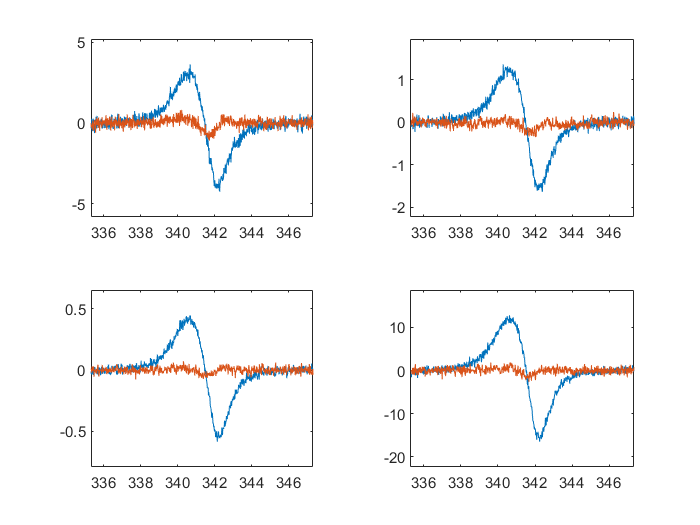

for icw = 1:ncw
    % y2 is the spectrum baseline and phase corrected
    [cw(icw).y2, cw(icw).Phase] = correctPhase(cw(icw).y1, 'Maximum');
    cw(icw).y = real(cw(icw).y2);
end

figure();
tiledlayout('flow');
for icw = 1:ncw;  nexttile; 
    plot(cw(icw).x, real(cw(icw).y2), cw(icw).x, imag(cw(icw).y2));
    xlim(setAxLim(cw(icw).x, 0)); ylim(setAxLim(real(cw(icw).y2), 0.2)); 
end

#### SNR

The SNR is calculated in two different ways:


$$SnrPp = \frac{A_{sig}}{A_{noise}}$$



$$SnrStdev = \frac{A_{sig}}{\sigma_{noise}}$$


$A_{sig}$ is calculated from the smoothened spectrum to avoid that spikes of noise could change the result. Care to avoid distortion of the signal is taken when setting the *m* parameter in the function *datasmooth.*

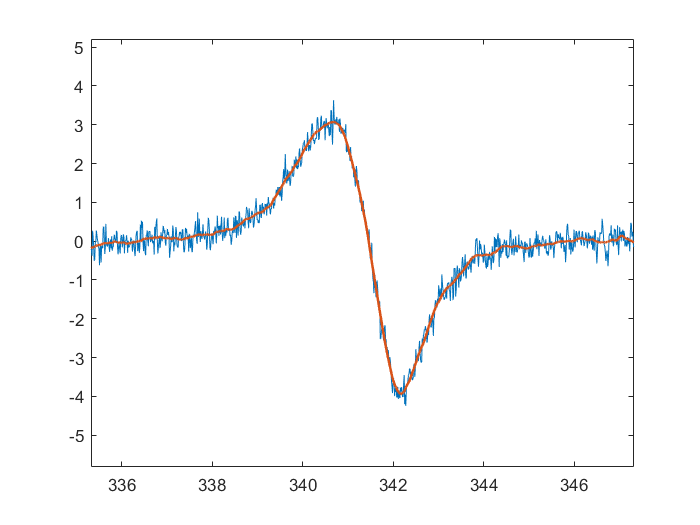

for icw = 1:ncw
    cw(icw).smoothY = datasmooth(cw(icw).y, 30, 'savgol');

    [~, cw(icw).ppAmp, ~] = ...
        getSNR(cw(icw).x, cw(icw).smoothY, Opt.Bl.Range, 'Stdev');
    [~, ~, cw(icw).NoiseStdev] = ...
        getSNR(cw(icw).x, cw(icw).y, Opt.Bl.Range, 'Stdev');
    [~, ~, cw(icw).NoisePp] = ...
        getSNR(cw(icw).x, cw(icw).y, Opt.Bl.Range, 'PeakToPeak');
    cw(icw).SnrStdev = cw(icw).ppAmp/cw(icw).NoiseStdev;
    cw(icw).SnrPp = cw(icw).ppAmp/cw(icw).NoisePp;
end

icw = 1;
figure()
plot(cw(icw).x, cw(icw).y)
hold on
plot(cw(icw).x, cw(icw).smoothY, 'Linewidth', 1.5)
xlim(setAxLim(cw(icw).x, 0)); ylim(setAxLim(cw(icw).y, 0.2));

#### SNR comparison

From the results one can notice that the measurements with amplifier settings 15x 1x and 1x 100x show better SNR. Not much more can be concluded, since one is a pure amplification before the last filter and one is a pure amplification after the last filter.

dispStr = 'Settings %s:\t%.1f, %.1f\n';
for icw = 1:ncw
    fprintf(dispStr, cw(icw).Title, cw(icw).SnrPp, cw(icw).SnrStdev)
end

Settings 15x 10x:	5.7, 31.4
Settings 5x 10x:	6.0, 36.0
Settings 15x 1x:	8.0, 43.8
Settings 1x 100x:	9.2, 51.1


#### Final plot

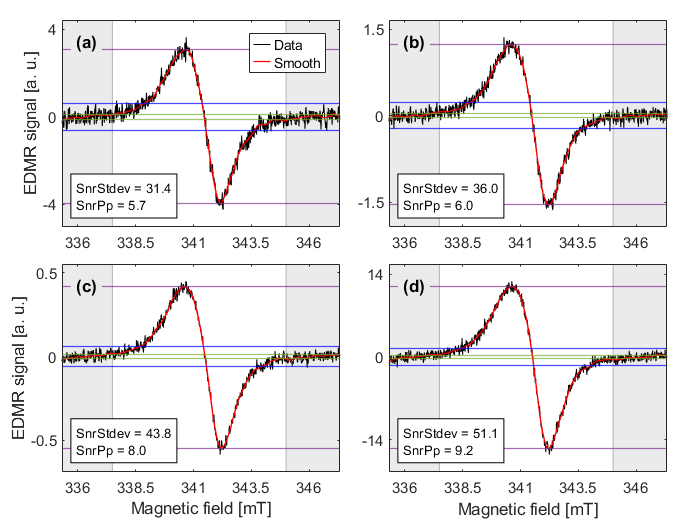

subplotID = ["(a)", "(b)", "(c)", "(d)"]; % 15x10x, 5x10x, 15x1x, 1x100x
figure()
tiledlayout('flow', 'TileSpacing', 'compact', 'Padding', 'compact')
LineW = 0.8;
gC = [0.4660 0.6740 0.1880]; % Green color
pC = [0.4940 0.1840 0.5560]; % Purple color
for icw = 1:ncw; nexttile
    plot(cw(icw).x, cw(icw).y, 'Color', [0 0 0])
    hold on
    plot(cw(icw).x, cw(icw).smoothY, 'r', 'Linewidth', LineW)
    rectangle('Position', [0 -50 Opt.Bl.Range(1, 2) 300], ...
        'FaceColor', [0.92 0.92 0.92], 'EdgeColor', [0.7 0.7 0.7]);
    rectangle('Position', [Opt.Bl.Range(2, 1) -50 200 300], ...
        'FaceColor', [0.92 0.92 0.92], 'EdgeColor', [0.7 0.7 0.7]);
    
    h = get(gca, 'Children');
    set(gca,'Children',[h(3) h(4) h(1) h(2)])
    set(gca, "Layer", "top")
    
    yline(cw(icw).NoiseStdev/2, 'Color', gC, 'Linewidth', LineW);
    yline(-cw(icw).NoiseStdev/2, 'Color', gC, 'Linewidth', LineW);
    yline(cw(icw).NoisePp/2, 'b', 'Linewidth', LineW);
    yline(-cw(icw).NoisePp/2, 'b', 'Linewidth', LineW);
    yline(max(cw(icw).smoothY), 'Color', pC, 'Linewidth', LineW);
    yline(min(cw(icw).smoothY), 'Color', pC, 'Linewidth', LineW);
    xlim(setAxLim(cw(icw).x, 0)); ylim(setAxLim(cw(icw).y, 0.1));
    xticks(336:2.5:346);
    if icw == 1 || icw == 3
        ylabel('EDMR signal [a. u.]', 'FontSize', 10)
    end
    if icw > 2
        xlabel('Magnetic field [mT]', 'FontSize', 10)
    end

    text(0.05, 0.9, subplotID(icw), 'Units', 'normalized', ...
        'FontWeight', 'bold', ...
        'FontSize', 10, ...
        'BackgroundColor', [0.92 0.92 0.92])
    annStr = {sprintf('SnrStdev = %.1f', string(cw(icw).SnrStdev)), ...
        sprintf('SnrPp = %.1f', string(cw(icw).SnrPp))};
    text(0.05, 0.15, annStr, 'Units', 'normalized', ...
        'FontSize', 8, ...
        'BackgroundColor', 'white', ...
        'EdgeColor', 'black');
    % title(cw(icw).Title)
end
nexttile(1); yticks([-4 0 4]); 
lgd = legend({'Data', 'Smooth'});
lgd.ItemTokenSize = [10 10 10];
nexttile(2); yticks([-1.5 0 1.5]);
nexttile(3); yticks([-0.5 0 0.5]);
nexttile(4); yticks([-14 0 14]);
exportgraphics(gcf, [Opt.SFolder, '/2021-06-17 Comparison preamp settings.png'])